# **WAVELET ANALYSIS**

**Wavelet analysis is a powerful technique for examining frequency and timing details of complex, non-stationary signals. Unlike Fourier transforms, the wavelet transform allows us to analyze how different frequency components vary over time, making it ideal for signals whose frequency structure changes during acquisition.**

clear; close all; clc;

Specify the parameters of a signal with a sampling frequency of 1 kHz and a signal duration of 1.5 seconds.

fs = 1000;            % Sampling frequency                    
ts = 1/fs;            % Sampling period       
l = 1500;             % Length of signal
t = (0:l-1)*ts;       % Time vector
f = fs*(0:(l/2))/l;   % Scaling

Form a signal of sinusoid with some frequencies

frequencies = [50, 100, 200, 300];
stationary_signal = 0.9*sin(2*pi*frequencies(1)*t) + sin(2*pi*frequencies(2)*t) ...
                  + 0.8*sin(2*pi*frequencies(3)*t) + 0.7*sin(2*pi*frequencies(4)*t);

Corrupt the signal with zero-mean white noise

non_stationary_signal = stationary_signal + 2*randn(size(t));

Plot the noisy signal in the time domain. It is difficult to identify the frequency components by looking at the signal x(t).

figure;
signal_slider =350;
subplot(211), plot(1000*t(1:signal_slider),non_stationary_signal(1:signal_slider)), grid;
title('Non stationary signal');
xlabel('t'), ylabel('x(t)');

Compute the Fourier transform of the signal.

X_non_stationary_signal = fft(non_stationary_signal);

Compute the two-sided spectrum P2. Then compute the single-sided spectrum P1 based on P2 and the even-valued signal length L.

mag_non_stationary_signal = abs(X_non_stationary_signal/l); 
half_mag_non_stationary_signal = mag_non_stationary_signal(1:l/2+1);
half_mag_non_stationary_signal(2:end-1) = 2*half_mag_non_stationary_signal(2:end-1);

Define the frequency domain f and plot the single-sided amplitude spectrum P1. The amplitudes are not exactly at 0.7 and 1, as expected, because of the added noise.

On average, longer signals produce better frequency approximations.

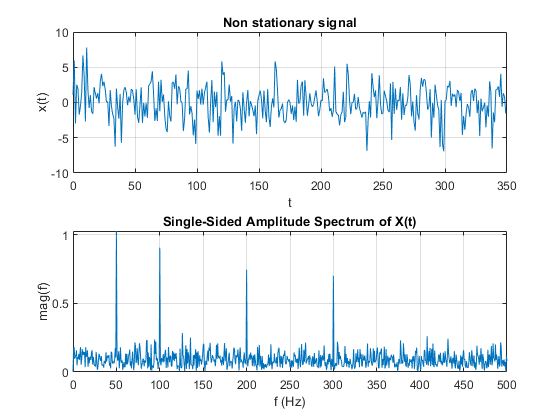

subplot(212), plot(f, half_mag_non_stationary_signal), grid;
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)'), ylabel('mag(f)');

Indeed, it can be noted that in the case of a stationary signal, the spectrum analysis is more difficult due to this additional "noise". Indeed, in this case, it is possible to confuse the small amplitude frequency components with the noise surrounding them. Therefore, for non-stationary signals it is recommended to use a different transformation that allows a more accurate analysis of the spectrum.

## Fast DWT - MALLAT ALGORITHM

The key idea of Mallat's algorithm is to represent a signal through a series of approximations and details at different scales. Initially, the signal is filtered with a low pass filter to obtain the low frequency approximation, i.e. the coarse details of the signal. Then, the same signal is filtered with a high-pass filter to extract high-frequency details. These steps are repeated sequentially to obtain a series of approximations and details at different scales.

After each filtering pass, subsampling occurs, which results in a reduction in the frequency of the signal. In practice, this means selecting every second sample of the signal, thus reducing the size of the data. This step is crucial to obtain an efficient and compact representation of the signal at different scales.

By repeating the process of filtering and subsampling, Mallat's algorithm creates a pyramid representation of the signal, where the approximations become increasingly "coarse" and higher-frequency details are captured at different scales. This pyramid representation offers a multi-resolution view of the signal, which is extremely useful in a variety of applications, such as data compression, image processing and signal analysis.

### Signal decomposition

In this case, being an application example, a 4-level decomposition will be used. Obviously this decomposition could be iterated for further levels

levels = 4;
initial_frequency = 1;  % 1 Hz = 6.28 rad/s
cutoff_frequency = initial_frequency/2;     % 0.5 Hz = 3.14 rad/s
subsampling_factor = 2;

The length of the signal is increased by introducing zeros in the tail so as not to have division problems when the filters are used at each level

target_length = 2048;
non_stationary_signal = [non_stationary_signal zeros(1, target_length-length(non_stationary_signal))];

#### 1st level

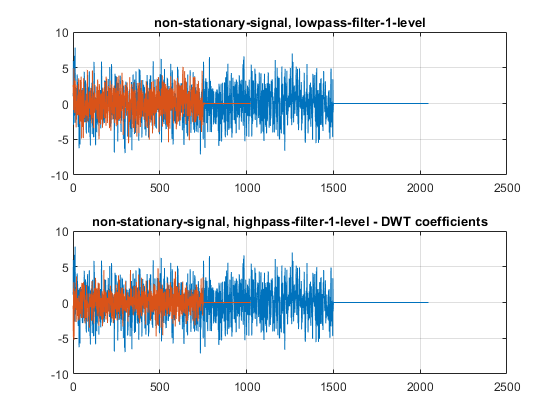

low_pass_1_level = lowpass(non_stationary_signal, cutoff_frequency);
low_pass_1_level = low_pass_1_level( 1 : subsampling_factor : end);
high_pass_1_level = highpass(non_stationary_signal, cutoff_frequency);
high_pass_1_level = high_pass_1_level( 1 : subsampling_factor : end);
figure;
subplot(211);
plot(1:1:target_length, non_stationary_signal(1:1:target_length));
hold on; 
plot(1:1:target_length/2, low_pass_1_level(1:1:target_length/2)), grid;
title('non-stationary-signal, lowpass-filter-1-level');
subplot(212);
plot(1:1:target_length, non_stationary_signal(1:1:target_length));
hold on; 
plot(1:1:target_length/2, high_pass_1_level(1:1:target_length/2)), grid;
title('non-stationary-signal, highpass-filter-1-level - DWT coefficients');

#### 2nd level

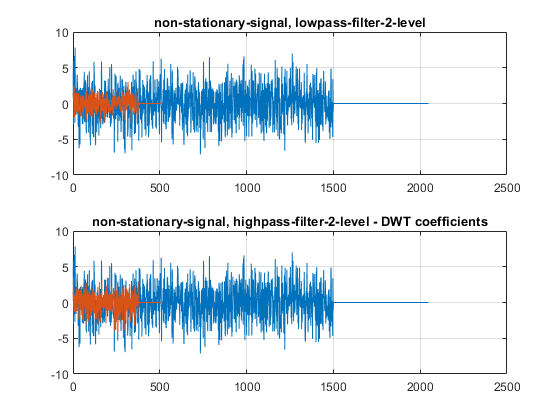

low_pass_2_level = lowpass(low_pass_1_level, cutoff_frequency/2);
low_pass_2_level = low_pass_2_level( 1 : subsampling_factor : end);
high_pass_2_level = highpass(high_pass_1_level, cutoff_frequency/2);
high_pass_2_level = high_pass_2_level( 1 : subsampling_factor : end);
figure;
subplot(211);
plot(1:1:target_length, non_stationary_signal(1:1:target_length));
hold on; 
plot(1:1:target_length/4, low_pass_2_level(1:1:target_length/4)), grid;
title('non-stationary-signal, lowpass-filter-2-level');
subplot(212);
plot(1:1:target_length, non_stationary_signal(1:1:target_length));
hold on; 
plot(1:1:target_length/4, high_pass_2_level(1:1:target_length/4)), grid;
title('non-stationary-signal, highpass-filter-2-level - DWT coefficients');

#### 3rd level

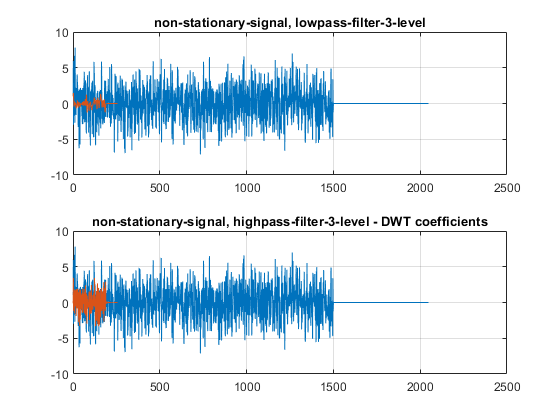

low_pass_3_level = lowpass(low_pass_2_level, cutoff_frequency/4);
low_pass_3_level = low_pass_3_level( 1 : subsampling_factor : end);
high_pass_3_level = highpass(high_pass_2_level, cutoff_frequency/4);
high_pass_3_level = high_pass_3_level( 1 : subsampling_factor : end);
figure;
subplot(211);
plot(1:1:target_length, non_stationary_signal(1:1:target_length));
hold on; 
plot(1:1:target_length/8, low_pass_3_level(1:1:target_length/8)), grid;
title('non-stationary-signal, lowpass-filter-3-level');
subplot(212);
plot(1:1:target_length, non_stationary_signal(1:1:target_length));
hold on; 
plot(1:1:target_length/8, high_pass_3_level(1:1:target_length/8)), grid;
title('non-stationary-signal, highpass-filter-3-level - DWT coefficients');

#### 4th level

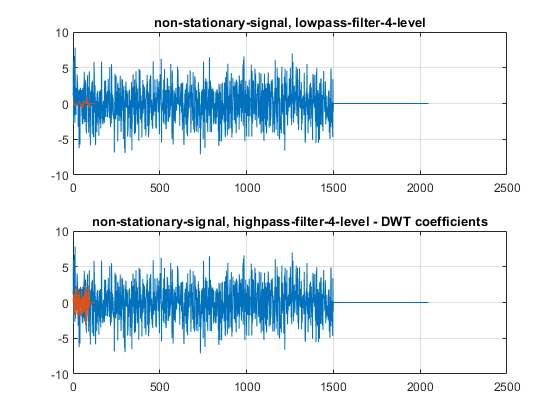

low_pass_4_level = lowpass(low_pass_3_level, cutoff_frequency/8);
low_pass_4_level = low_pass_4_level( 1 : subsampling_factor : end);
high_pass_4_level = highpass(high_pass_3_level, cutoff_frequency/8);
high_pass_4_level = high_pass_4_level( 1 : subsampling_factor : end);
figure;
subplot(211);
plot(1:1:target_length, non_stationary_signal(1:1:target_length));
hold on; 
plot(1:1:target_length/16, low_pass_4_level(1:1:target_length/16)), grid;
title('non-stationary-signal, lowpass-filter-4-level');
subplot(212);
plot(1:1:target_length, non_stationary_signal(1:1:target_length));
hold on; 
plot(1:1:target_length/16, high_pass_4_level(1:1:target_length/16)), grid;
title('non-stationary-signal, highpass-filter-4-level - DWT coefficients');

### **Signal reconstruction**

In Mallat's algorithm, the reconstruction of the signal starting from the approximations and details obtained through the wave decomposition takes place through an inverse process. This process involves the use of lowpass and highpass filters, along with the upsampling pass.

After obtaining the approximations and details at different scales through wave decomposition, the reconstruction process begins with the upsampling phase. Upsampling involves expanding the signal to twice the frequency of its original sampled frequency. This means that zeros are added between signal samples to increase their size.

Next, the upsampled signal is filtered with a lowpass filter and a highpass filter. The low-pass filter is used to reconstruct the approximation of the low-frequency signal, while the high-pass filter is used to reintroduce high-frequency detail. These filters are designed to be the "conjugates" of the filters used in the decomposition step.

The outputs of the lowpass and highpass filters are then summed to obtain a single approximation of the reconstruction. This approximation is associated with the higher (coarser) scale of the wave decomposition. The reconstruction process continues iterating through the different scales, gradually adding high-frequency detail to achieve a complete reconstruction of the original signal.

The entire reconstruction process using Mallat's algorithm uses upsampling and low-pass/high-pass filters to combine the approximations and details at different scales and obtain a final approximation of the original non-stationary signal. This technique is particularly useful in applications where it is desired to analyze and manipulate non-stationary signals, such as in image processing, data compression, and many other areas of signal processing and data analysis.

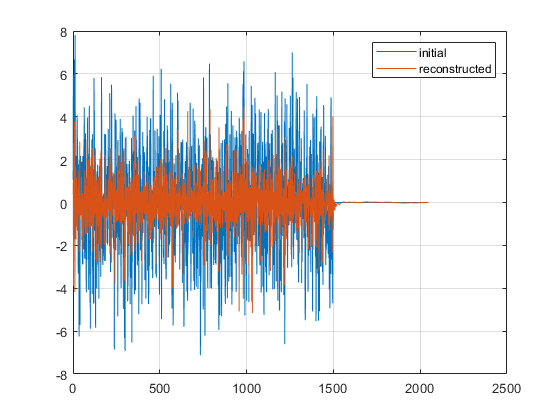

lowpass_cutoff_frequencies_reconstruction = [0.48296, 0.8365, 0.22414, -0.12941];
highpass_cutoff_frequencies_reconstruction = [-0.12941, -0.22414, 0.8365, -0.48296];

upsampling_factor = 2;


high_pass_4_level_upsampled = upsample(high_pass_4_level, upsampling_factor);
low_pass_4_level_upsampled = upsample(low_pass_4_level, upsampling_factor);
high_pass_4_level_upsampled_tosum = highpass(high_pass_4_level_upsampled, cutoff_frequency/16);
low_pass_4_level_upsampled_tosum = lowpass(low_pass_4_level_upsampled, cutoff_frequency/16);
level_4 = high_pass_4_level_upsampled_tosum + low_pass_4_level_upsampled_tosum;

high_pass_3_level_upsampled = upsample(high_pass_3_level, upsampling_factor);
low_pass_3_level_upsampled = upsample(level_4, upsampling_factor);
high_pass_3_level_upsampled_tosum = highpass(high_pass_3_level_upsampled, cutoff_frequency/8);
low_pass_3_level_upsampled_tosum = lowpass(low_pass_3_level_upsampled, cutoff_frequency/8);
level_3 = high_pass_3_level_upsampled_tosum + low_pass_3_level_upsampled_tosum;

high_pass_2_level_upsampled = upsample(high_pass_2_level, upsampling_factor);
low_pass_2_level_upsampled = upsample(level_3, upsampling_factor);
high_pass_2_level_upsampled_tosum = highpass(high_pass_2_level_upsampled, cutoff_frequency/4);
low_pass_2_level_upsampled_tosum = lowpass(low_pass_2_level_upsampled, cutoff_frequency/4);
level_2 = high_pass_2_level_upsampled_tosum + low_pass_2_level_upsampled_tosum;

high_pass_1_level_upsampled = upsample(high_pass_1_level, upsampling_factor);
low_pass_1_level_upsampled = upsample(level_2, upsampling_factor);
high_pass_1_level_upsampled_tosum = highpass(high_pass_1_level_upsampled, cutoff_frequency/2);
low_pass_1_level_upsampled_tosum = lowpass(low_pass_1_level_upsampled, cutoff_frequency/2);
level_1 = high_pass_1_level_upsampled_tosum + low_pass_1_level_upsampled_tosum;

reconstructed_signal = level_1;

figure, plot(1:1:target_length, non_stationary_signal), hold on, plot(1:1:target_length, reconstructed_signal);
legend('initial','reconstructed'), grid;

### **Audio comparison**

To verify the correspondence between the original signal and the reconstructed one, it is assumed that this signal is an audio signal. Therefore, we proceed with an audio comparison

player_nonstationary_signal = audioplayer(non_stationary_signal, fs);
play(player_nonstationary_signal);
pause(5);
player_reconstructed_signal = audioplayer(reconstructed_signal, fs);
play(player_reconstructed_signal);

### **Error analysis**

Furthermore, the error occurs, i.e. how much the reconstructed signal deviates from the original signal

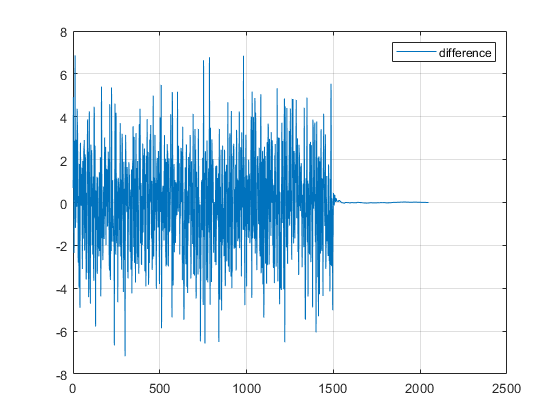

figure, plot(1:1:target_length, non_stationary_signal-reconstructed_signal), legend('difference'), grid;